# EMT Basic Functionalities

## **Initialize EPANET-MATLAB Toolkit**

Load all the paths in MATLAB. You should always begin with this command to load the toolkit.

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


If you get an error message:

`'start_toolkit' is not found in the current folder or on the MATLAB path, but exists in:`

It means that you need to change the MATLAB current folder.

**Load a benchmark network**

Decide which benchmark network to use and load the network

% decide which network to load from the "/networks/" folder  
filename = 'net2-cl2.inp'; % you can also try 'net2-cl2.inp', 'Net3.inp', etc.

%call epanet class and load all data and functions in G structure
G = epanet(filename)

EPANET version {20200} loaded (EMT version {v2.2.2 - Last Update: 07/08/2022}).
Loading File "net2-cl2.inp"...
Input File "net2-cl2.inp" loaded successfully.


G =   epanet with properties:

                                   ph: [1×1 lib.pointer]
                   ControlLevelValues: []
                     ControlLinkIndex: []
                     ControlNodeIndex: []
                         ControlRules: []
                    ControlRulesCount: 0
                             Controls: [1×1 struct]
                      ControlSettings: []
                         ControlTypes: {}
                    ControlTypesIndex: []
                           CurveCount: 0
                           CurveIndex: [1×0 int32]
                           CurvesInfo: [1×1 struct]
                      DemandModelCode: 0
                      DemandModelPmin: 0
                      DemandModelPreq: 0.1
                      DemandModelPexp: 0.5
                      DemandModelType: {'DDA'}
                EnergyEfficiencyUnits: 'percent'
                          EnergyUnits: 'kwatt-hours'
 

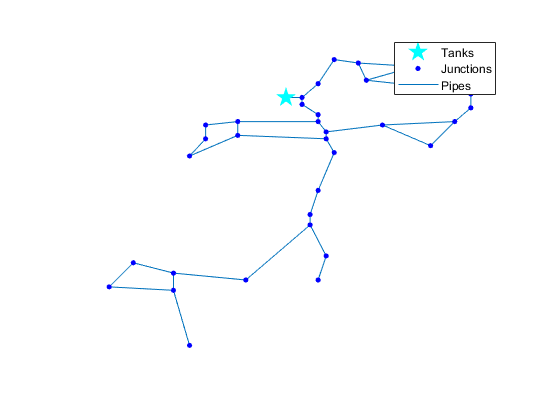

ans =   Axes with properties:

             XLim: [6.5 60.5]
             YLim: [-4.3 95.3]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.775 0.815]
            Units: 'normalized'

  Show all properties


G.plot

## **Running your first analysis**

There are 4 ways to run a simulation using the Toolkit

- Using the batch hydraulic/quality analysis function

- Using the iterative (step-by-step) hydraulic/quality analysis function

- Using the ENepanet function binary file

- Using the command line and the binary file

% set simulation duration at hours 
hrs = 48 

hrs =     48


G.setTimeSimulationDuration(3600*hrs)

Execute the simulation using the batch hydraulic analysis method

H = G.getComputedHydraulicTimeSeries 

H = struct with fields:
             Time: [49×1 double]
         Pressure: [49×36 double]
           Demand: [49×36 double]
    DemandDeficit: [49×36 double]
             Head: [49×36 double]
       TankVolume: [49×36 double]
             Flow: [49×40 double]
         Velocity: [49×40 double]
         HeadLoss: [49×40 double]
           Status: [49×40 double]
          Setting: [49×40 double]
           Energy: [49×40 double]
       Efficiency: [49×40 double]
            State: [49×0 double]
        StatusStr: {49×40 cell}
         StateStr: {49×0 cell}


Execute the simulation using the batch quality analysis method

Q = G.getComputedQualityTimeSeries

Q = struct with fields:
            Time: [577×1 double]
     NodeQuality: [577×36 double]
     LinkQuality: [577×40 double]
    MassFlowRate: [577×36 double]


## Other methods  to run EPANET

Method using the binary result file

Hbin = G.getBinComputedAllParameters 

Hbin = struct with fields:
         BinNumberReportingPeriods: 56
                    Binmagicnumber: 516114521
                      BinLibEPANET: 20012
                    BinNumberNodes: 36
          BinNumberReservoirsTanks: 1
                    BinNumberLinks: 40
                    BinNumberPumps: 0
                   BinNumberValves: 0
             BinWaterQualityOption: 1
         BinIndexNodeSourceTracing: 0
                BinFlowUnitsOption: 1
            BinPressureUnitsOption: 0
             BinTimeStatisticsFlag: 0
          BinReportingStartTimeSec: 0
           BinReportingTimeStepSec: 3600
          BinSimulationDurationSec: 198000
                  BinProblemTitle1: 'EPANET Example Network 2                                                        '
                  BinProblemTitle2: '                                                                                '
                  BinProblemTitle3: '                                                                   

Method using the EPANET executable

Hexe = G.getComputedTimeSeries

Hexe = struct with fields:
              Time: [49×1 double]
          Pressure: [49×36 double]
            Demand: [49×36 double]
              Head: [49×36 double]
       NodeQuality: [49×36 double]
              Flow: [49×40 double]
          Velocity: [49×40 double]
          HeadLoss: [49×40 double]
            Status: [49×40 double]
           Setting: [49×40 double]
      ReactionRate: [49×40 double]
    FrictionFactor: [49×40 double]
       LinkQuality: [49×40 double]
         StatusStr: {49×40 cell}


Method using the ENepanet library function (fastest)

Hbatch = G.getComputedTimeSeries_ENepanet

Hbatch = struct with fields:
              Time: [49×1 double]
          Pressure: [49×36 double]
            Demand: [49×36 double]
              Head: [49×36 double]
       NodeQuality: [49×36 double]
              Flow: [49×40 double]
          Velocity: [49×40 double]
          HeadLoss: [49×40 double]
            Status: [49×40 double]
           Setting: [49×40 double]
      ReactionRate: [49×40 double]
    FrictionFactor: [49×40 double]
       LinkQuality: [49×40 double]
         StatusStr: {49×40 cell}


## Plot results

% Get pressure in meters
P = H.Pressure

P =           112.607933044434          88.9210510253906          105.981010437012          105.800415039062          88.4516296386719          76.7385330200195          59.6288948059082          81.2932434082031          50.6943168640137          72.6266632080078          48.0835075378418          36.2104949951172          35.9047546386719          40.0956153869629          44.3498268127441          61.6915092468262          48.6737480163574          83.3359146118164          61.6743202209473          53.0837364196777          61.7395668029785          40.0747108459473          26.8263111114502           44.290355682373          26.7640571594238            70.08544921875          78.7495193481445          78.7495880126953           70.083137512207          44.0925712585449          79.0028839111328           48.740291595459          44.4072418212891          78.7495574951172          78.7495040893555          24.5681095123291
          113.449089050293            89.76220703125       

F = H.Flow

F =             666.6240234375          548.364196777344          108.179801940918          90.5398025512695          80.4598007202148          618.744018554688          612.443969726562          17.6399993896484          589.763977050781          6.30000019073486            572.1240234375          528.301208496094          508.141204833984          418.268920898438          355.268920898438          87.3522644042969          15.9677324295044          38.7568969726562          29.5246276855469           4.3246283531189          23.3953723907471          60.4799995422363          18.3389358520508         -1.82106375694275          18.2010631561279          322.921203613281          336.781188964844          312.841186523438          259.921203613281          45.3600006103516          23.9400005340576          13.8599996566772           2.5734076499939          3.77999997138977          1.88999998569489         -17.0953712463379          2.46659231185913          3.77999997138977        

C = Q.NodeQuality

C =                        0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5                       0.5         0.100000001490116
         0.800000011920929         0.493474304676056       


% Translate time to plots 
T = H.Time

T =            0
        3600
        7200
       10800
       14400
       18000
       21600
       25200
       28800
       32400


Tcl = Q.Time

Tcl =            0
         300
         600
         900
        1200
        1500
        1800
        2100
        2400
        2700


TD = datetime(2022,7,18,0,0,T) % specify datetime structure

TD = 49×1 datetime array
   18-Jul-2022 00:00:00
   18-Jul-2022 01:00:00
   18-Jul-2022 02:00:00
   18-Jul-2022 03:00:00
   18-Jul-2022 04:00:00
   18-Jul-2022 05:00:00
   18-Jul-2022 06:00:00
   18-Jul-2022 07:00:00
   18-Jul-2022 08:00:00
   18-Jul-2022 09:00:00
   18-Jul-2022 10:00:00
   18-Jul-2022 11:00:00
   18-Jul-2022 12:00:00
   18-Jul-2022 13:00:00
   18-Jul-2022 14:00:00
   18-Jul-2022 15:00:00
   18-Jul-2022 16:00:00
   18-Jul-2022 17:00:00
   18-Jul-2022 18:00:00
   18-Jul-2022 19:00:00
   18-Jul-2022 20:00:00
   18-Jul-2022 21:00:00
   18-Jul-2022 22:00:00
   18-Jul-2022 23:00:00
   19-Jul-2022 00:00:00
   19-Jul-2022 01:00:00
   19-Jul-2022 02:00:00
   19-Jul-2022 03:00:00
   19-Jul-2022 04:00:00
   19-Jul-2022 05:00:00
   19-Jul-2022 06:00:00
   19-Jul-2022 07:00:00
   19-Jul-2022 08:00:00
   19-Jul-2022 09:00:00
   19-Jul-2022 10:00:00
   19-Jul-2022 11:00:00
   19-Jul-2022 12:00:00
   19-Jul-2022 13:00:00
   19-Jul-2022 14:00:00
   19-Jul-2022 15:00:00
   19-Jul-2022 

TQ = datetime(2022,7,18,0,0,Tcl) % specify datetime structure

TQ = 577×1 datetime array
   18-Jul-2022 00:00:00
   18-Jul-2022 00:05:00
   18-Jul-2022 00:10:00
   18-Jul-2022 00:15:00
   18-Jul-2022 00:20:00
   18-Jul-2022 00:25:00
   18-Jul-2022 00:30:00
   18-Jul-2022 00:35:00
   18-Jul-2022 00:40:00
   18-Jul-2022 00:45:00
   18-Jul-2022 00:50:00
   18-Jul-2022 00:55:00
   18-Jul-2022 01:00:00
   18-Jul-2022 01:05:00
   18-Jul-2022 01:10:00
   18-Jul-2022 01:15:00
   18-Jul-2022 01:20:00
   18-Jul-2022 01:25:00
   18-Jul-2022 01:30:00
   18-Jul-2022 01:35:00
   18-Jul-2022 01:40:00
   18-Jul-2022 01:45:00
   18-Jul-2022 01:50:00
   18-Jul-2022 01:55:00
   18-Jul-2022 02:00:00
   18-Jul-2022 02:05:00
   18-Jul-2022 02:10:00
   18-Jul-2022 02:15:00
   18-Jul-2022 02:20:00
   18-Jul-2022 02:25:00
   18-Jul-2022 02:30:00
   18-Jul-2022 02:35:00
   18-Jul-2022 02:40:00
   18-Jul-2022 02:45:00
   18-Jul-2022 02:50:00
   18-Jul-2022 02:55:00
   18-Jul-2022 03:00:00
   18-Jul-2022 03:05:00
   18-Jul-2022 03:10:00
   18-Jul-2022 03:15:00
   18-Jul-2022

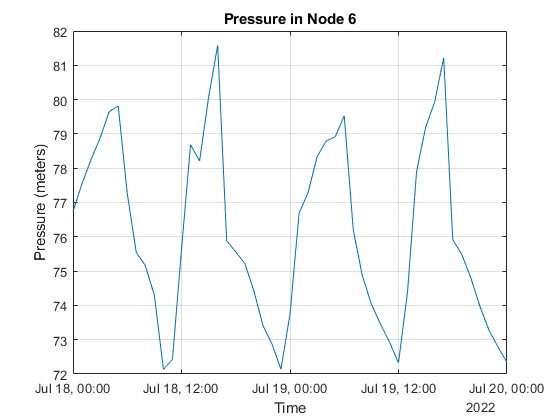


% Plot
figure
plot(TD,P(:,6))
grid on
title(['Pressure in Node ',G.getNodeNameID{6}])
ylabel('Pressure (meters)')
xlabel('Time')


pipeindex=G.getLinkIndex('1')

pipeindex = int32
   1


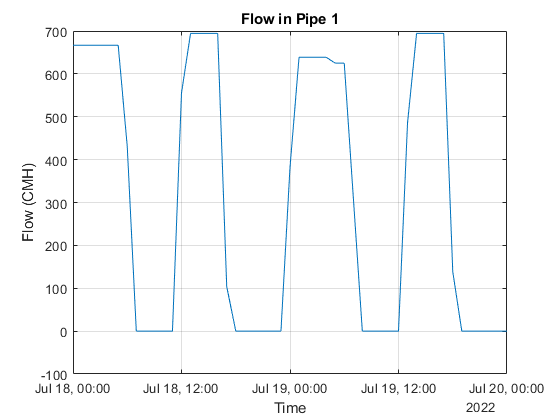

figure
plot(TD,F(:,pipeindex))
grid on
title(['Flow in Pipe ',G.getLinkNameID{pipeindex}])
ylabel('Flow (CMH)')
xlabel('Time')

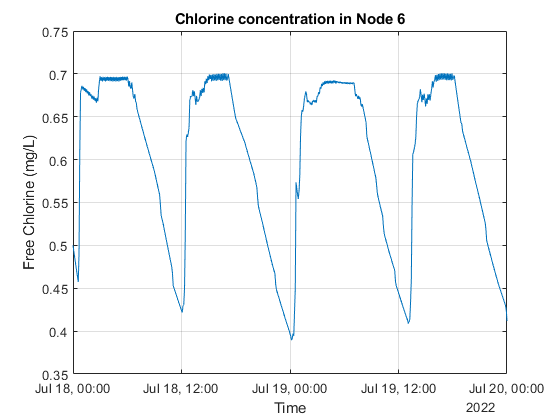


figure
plot(TQ,C(:,6))
grid on
title(['Chlorine concentration in Node ',G.getNodeNameID{6}])
ylabel('Free Chlorine (mg/L)')
xlabel('Time')



% Your turn: Plot Chlorine in node with index 10 




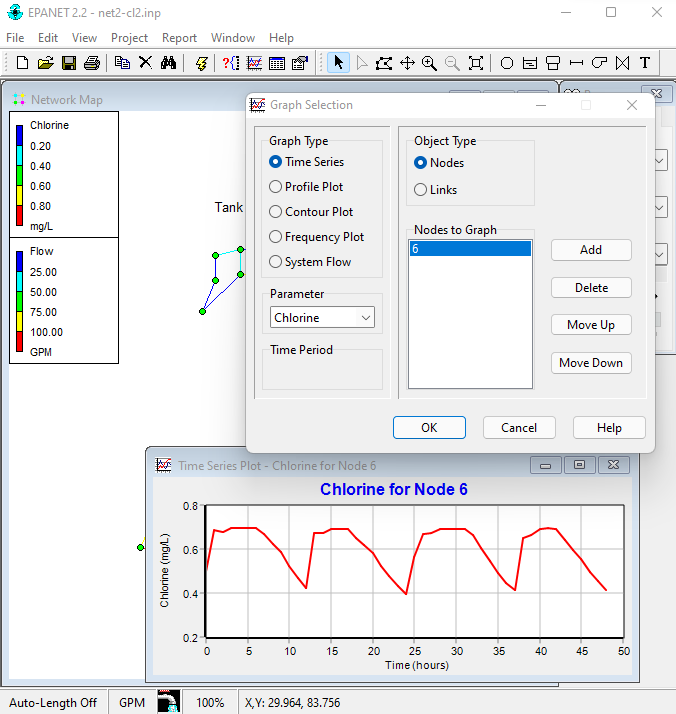

**Plot node pressures for specific nodes **

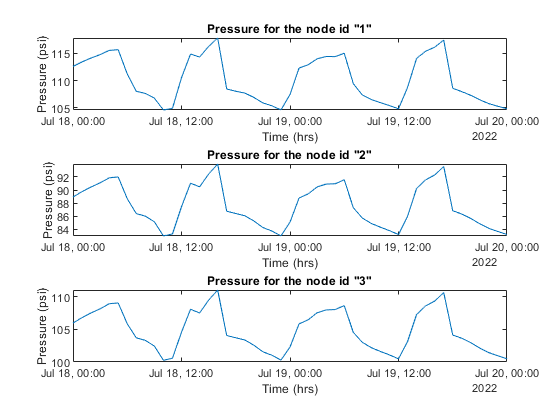

node_indices = [1, 2, 3];
node_names = G.getNodeNameID(node_indices);
figure;
for k=1:length(node_indices)
    subplot(3,1,k)    
    plot(TD, P(:,node_indices(k)));
    title(['Pressure for the node id "', G.getNodeNameID{node_indices(k)},'"']);
    xlabel('Time (hrs)'); 
    ylabel(['Pressure (', G.NodePressureUnits,')'])
end

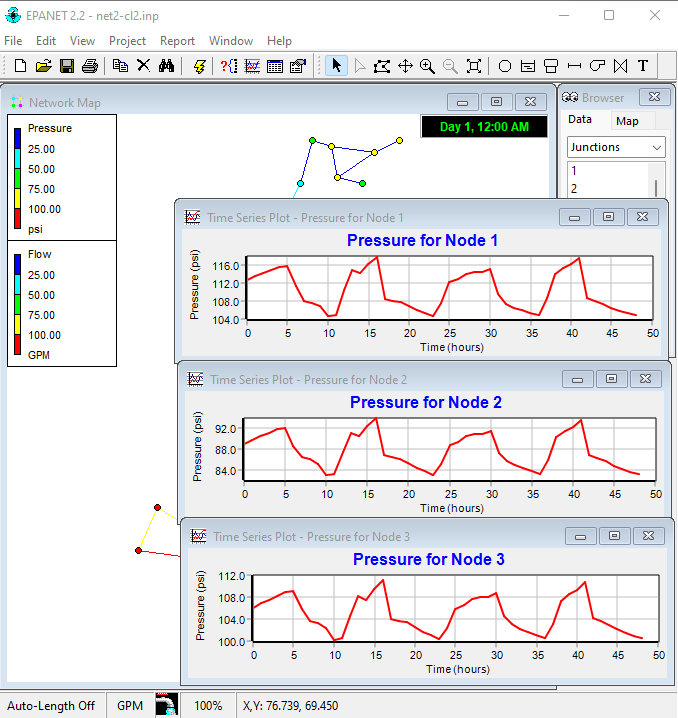

## Iteratively (step-by-step) hydraulic analysis

% 4 steps to run hydraulics
G.openHydraulicAnalysis; % Step 1
G.initializeHydraulicAnalysis; % Step 2

tstep=1;P2=[];T2=[];D2=[];H2=[];F2=[];

while (tstep>0)
    ttmp = G.runHydraulicAnalysis; % Step 3
    P2=[P2; G.getNodePressure];
    D2=[D2; G.getNodeActualDemand];
    H2=[H2; G.getNodeHydaulicHead];
    F2=[F2; G.getLinkFlows];
    T2=[T2; ttmp];
    tstep=G.nextHydraulicAnalysisStep; % Step 4
end

G.closeHydraulicAnalysis;

Plot figures

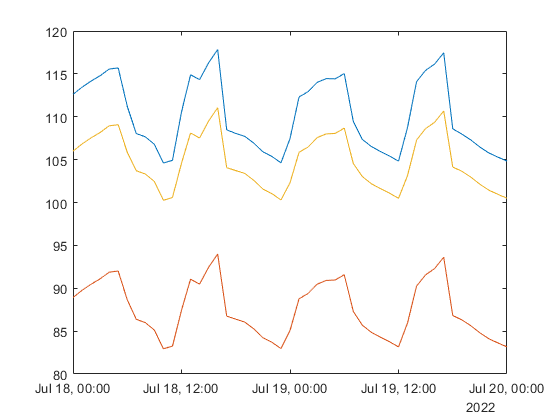

figure
plot(TD, P2(:, node_indices))

## Iteratively (step-by-step) quality analysis

% requires solveCompleteHydraulics
G.openQualityAnalysis
G.initializeQualityAnalysis
tleft=1; QT=[];QsN=[]; QsL=[]; 
while (tleft>0)
    ttmp=G.runQualityAnalysis;
    QsN=[QsN; G.getNodeActualQuality];
    QsL=[QsL; G.getLinkActualQuality];
    QT=[QT; ttmp];
    tleft = G.stepQualityAnalysisTimeLeft;
end
G.closeQualityAnalysis;

Plot figures

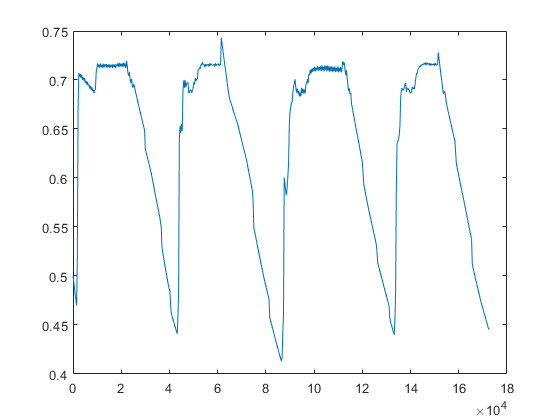

figure
plot(QT, QsN(:, 5))